clc
close all
warning('off','all')
global alpha_cmpst h k_cmpst Ti Tamb egen answer1

### Step 1: Import Product Paramters

Optimal temperature and expected shelf-life

ProdData=readtable('Input Files/FruitData.xlsx',"Sheet",'OneTimeInput');
% Mean optimal temperature
To=mean([ProdData.To_L ProdData.To_U]);

% Mean of the maximum shelf life at the optimal temperature
MSL=mean([ProdData.MSL_L ProdData.MSL_U]); %days
% Initial Shelf Life Estimate in days
SL0=ProdData.SL0;

% If an estimate of the initial shelf life is not provided by the user, estimate it 
% to be the mean of max shelf life range, less the time since harvest

if isnan(SL0)
    SL0=MSL-ProdData.ST; %days
end

% Converting the initial shelf life from days to hours
SL0=SL0*24;

Environmental + Packaging conditions


% Air velocity
V=ProdData.V; 
if isnan(V)
    V=0;
end

% Read constants in the equation Nu= a * Re^n *Pr^m Gr^q
a_h=ProdData.a_h;
n_h=ProdData.n_h;
m_h=ProdData.m_h;
q_h=ProdData.q_h;


% Air-tight or open-air conditions?

IsAirTight=strcmp(ProdData.IsAirTight,"Y")==1;

% Read initial volume of headspace air (mL)
Vhsair=ProdData.Vhsair;

if IsAirTight
    % Read the macroscopic porosity
     airfrac=ProdData.tpairfrac; 
     % Read mass of product in kg
     massprd=ProdData.massprd;


else
     % Set the the stacking porosity to zero
     airfrac=0; 
     % Set mass of product to 1 kg
     massprd=1; 
end

Thermophysical properties

% Fruit's thermal diffusivity

alpha_so=ProdData.alpha_s; 

% Thermal conductivity

if isnan(ProdData.k_s) % if the user has not provided a single constant thermal conductivity
   
    % read the table of thermal conductivity at each temperature
    ksM = readmatrix('Input Files/FruitData.xlsx','Sheet','Ks_Temp','Range','A2');
    
else % if user provided a single value for thermal conductivity
    
    k_so=ProdData.k_s;
    
    
end

% Bulk density of fruit (kg/m3)
rho_s= ProdData.rho_s; 


Geometric properties

% Characteristic Length (m), the distance from the thermal center to the surface
Lc=ProdData.Lc;  
% type of symmetry
symtype = ProdData.m; 

### Step 2: Import Temperature-RH-Time Logs

optsSensorImport = spreadsheetImportOptions('NumVariables',3,'DataRange','A2','Sheet','TempRH',"VariableTypes",{'double','double','double'});
SensorData=readtable("Input Files/SensorFeed.xlsx",optsSensorImport);

% Read time stamp (first column)
time_rt=SensorData.Var1;

% Read ambient temperature (second column)
ambtemp_rt=SensorData.Var2;

% Read relative humidity (third column)
RH0=SensorData.Var3;

RH=RH0;


if IsAirTight % If product is air-tight, assume 100% RH
    
   RH=ones(size(RH0));

    
end


% If no RH readings are provided (vector is all zeros or all NaNs), prompt the user for an average RH. If
% user doesn't provide this either, then assume 95% relative humidity.
    
if not(any(RH))
    
    RH_avg=input('Enter the average relative humidity as a decimal (0-1)');
    
        if isempty(RH_avg)==1
            
        RH=ones(size(RH0))*0.95;
        
        else
            
        RH=RH_avg*ones(size(RH0));
        
        end
end


Preallocating vectors to improve speed

% Vectors to store calculated pulp and surface temperatures over time
pulpTemp=zeros(size(time_rt)); 
Ts=zeros(size(time_rt));

% Calculated properties of humid air (trapped air pockets)
rho_tpa=zeros(size(time_rt)); %  density 
k_tpa=zeros(size(time_rt)); % thermal conductivity
cp_tpa=zeros(size(time_rt)); %  specific heat capacity 

% Calculated properties of humid air (enclosed headspace air)
rho_hsa=zeros(size(time_rt)); %  density 
mu_hsa=zeros(size(time_rt)); %  viscosity
k_hsa=zeros(size(time_rt)); %  thermal conductivity
cp_hsa=zeros(size(time_rt)); %  specific heat capacity 


hhold=zeros(size(time_rt)); % Vector of the estimated values of the convection coefficient h over time
CRR=zeros(size(time_rt)); % Vector of the calculated respiration rate over time
OptRR=zeros(size(time_rt)); % Vector of the optimal respiration rate over time
cps=zeros(size(time_rt)); % Product's specific heat capacity, determined relative to the product's freezing temperature
cps_cmpst=zeros(size(time_rt)); % Product's specific heat capacity, modified for stacking porosity
rho_cmpst=zeros(size(time_rt)); % effective density of composite body


CO2Vol=zeros([length(time_rt) 1]); % Volume of CO2 in packaging over time
vol_tpair=zeros([length(time_rt) 1]); % Volume of trapped air pockets
vol_hsair=zeros([length(time_rt) 1]); % Volume of enclosed headspace air
vol_air=zeros([length(time_rt) 1]); % Volume of air trapped inside the packaging
CO2conc=zeros([length(time_rt) 1]); % CO2 concentration in packaging over time


% An indicator of whether CO2 level has exceeded the maximum tolerable
% limit. Initialized to zero.
fermentationStage=0;

Ensuring sensor data have been sampled at a fixed interval


if strcmp(answer1,"Post-trip analysis")==0
% If the plant has been identified (and therefore the temperature logs are simulated)
% then Import sensor sampling period from plantparameters.mat
    load plantparameters.mat SST;
else
%Otherwise, prompt the user for a fixed sampling interval and then
% resample the temperature history
    SST=input('Input Data Resampling Period (minutes)');
    [ambtemp_rt,time_rt]=resample(ambtemp_rt,time_rt,1/SST);
end


### Step 3: Import Product Respiration Profile

RespData=readmatrix('Input Files/FruitData.xlsx',"Sheet","Decay Profile");

% Temperature (first column)
temp_d=RespData(:,1);
% Storage time in minutes (second column)
storageTime=RespData(:,2);
% CO2 concentration (third column)
CO2Conc_d=RespData(:,3);
% CO2 volume produced (in mL) (fourth column)
CO2_ml=RespData(:,4);

###  Step 4: Construct the respiration rate function

if IsAirTight

  RespRate_ANR = scatteredInterpolant(temp_d,storageTime,CO2Conc_d,CO2_ml,'linear','linear');

else
    
  RespRate_AR = scatteredInterpolant(temp_d,storageTime,CO2_ml,'linear',"linear");  

end



### Steps 5-7: Initialize CO2 volume, concentration, and total air volume in packaging

% Initial CO2 concentration set to 0.04%, which is the concentration of CO2
% in standard atmospheric composition
CO2conc(1)=0.04e-02;

% Volume of trapped air pockets (mL)
vol_tpair(1)=massprd*1e+06*(airfrac./(1-airfrac))./rho_s;

% Mass of trapped air pockets within the bunched product

    % find the density of ambient air at 100% RH (g/mL)

rho_tpa(1)=MoistAirProperties(To,1)*1e-03;

    % multiply by the volume of trapped air pockets (mL x g/mL = g)
   
mass_tpair=vol_tpair(1)*rho_tpa(1); % grams


vol_hsair(1)=Vhsair;
% Mass of headspace air in the package

    % find the density of ambient air at 100% RH (g/mL)

rho_hsa(1)=MoistAirProperties(ambtemp_rt(1),1)*1e-03;

    % multiply by the volume of headspace air provided by the user (mL)
   
mass_hsair=vol_hsair(1)*rho_hsa(1); % grams


% Total volume of air in the package (mL)
vol_air(1)=vol_tpair(1)+vol_hsair(1);


% Initial value of the volume of CO2 in packaging (mL)
CO2Vol(1)=CO2conc(1)*vol_air(1); 


### Step 8:  Initialize pulp and surface temperatures of fruit to the optimal handling temperature (deg C)

Ti=To;

Ts(1)=To; 


### Step 9: Times and locations for which the PDE solution will be provided

xmesh = [0 Lc/2 Lc]; % locations are center, midplane, and surface
tspan = [0 SST*60/2 SST*60];
 

f = waitbar(0, 'Starting');
n = length(time_rt);


### Step 10: Begin loop through ambient temperature history

for i=1:n
    
    Tamb=ambtemp_rt(i); % Ambient temperature (deg C)
    
    

###  Step 11: Compute humid air properties at current ambient temperature and relative humidity 

    [rho_hsa(i),mu_hsa(i),k_hsa(i),cp_hsa(i)]=MoistAirProperties(ambtemp_rt(i),RH(i));
    
    [rho_tpa(i),~,k_tpa(i),cp_tpa(i)]=MoistAirProperties(Ti,RH(i));
         

### Step 12: Read or compute current surface convection coefficient h

     if ~isnan(ProdData.h)
       h=ProdData.h; % Coefficient of convection (W/m2.deg C) 
       
     else
         
       if isnan(a_h) % No Nu-Re-Pr or Nu-Or-Gr correlation provided
       hhold(i)=NatConvecCoeff(rho_hsa(i),mu_hsa(i),k_hsa(i),cp_hsa(i),symtype,Lc*2,ambtemp_rt(i),Ts(i));
       else
       hhold(i)=ForcedConvecCoeff(rho_hsa(i),mu_hsa(i),k_hsa(i),cp_hsa(i),V,Lc*2,a_h,m_h,n_h,q_h,ambtemp_rt(i),Ts(i));
       end
       
       h=hhold(i); 
     end
     

### Steps 13: Compute current respiration rate

     if IsAirTight
     
        CRR(i)=max(0,RespRate_ANR(Ti,time_rt(i),CO2conc(i)));
   
     else
         
        CRR(i)=max(0,RespRate_AR(Ti,time_rt(i)));
        
     end
    
  

### Step 14:  

a) Compute volume of CO2 evolved  

b) Compute the mass of CO2 evolved using the ideal gas law.

 For air-tight sealed products:

c) Calculate  and  using ideal gas law, assuming constant air masses, atmospheric pressure, and that trapped air pockets are at midplane temperature, while headspace air is at measured ambient temperature

d) Update total air volume: 

e) Increment total volume of  CO2  in the container for the next time step. To avoid invalid results, choose the minimum of the current CO2 volume or the free container volume.

f) Compute CO2  concentration in the next time step,.

g) Check if the product’s maximum tolerable CO2 concentration has been reached.

For open/highly porous packaging:

h) Keep total volume of  CO2  same as in the previous time step

i) Keep CO2  concentration in the next time step,  at 0.04% (standard atmospheric composition)                          

     % Step 14 a)    
     
    CO2_ml_produced=CRR(i)*massprd*SST/60;
   
     % Step 14 b) 
     
    CO2_g_produced=101325*44.0095*CO2_ml_produced*1e-06./(8.314*(ambtemp_rt(i)+273.15));
    
    if IsAirTight
       
     % Step 14 c)
  
       vol_tpair(i+1)=(mass_tpair*8.314*(Ti+273.15))*1e+6./(28.97*101325);
       
       vol_hsair(i+1)=(mass_hsair*8.314*(Tamb+273.15))*1e+6./(28.97*101325);
       
     % Step 14 d)
     
       vol_air(i+1)=vol_hsair(i+1)+vol_tpair(i+1);
       
        
     % Step 14 e) 
    
        CO2Vol(i+1)=min(CO2Vol(i)+CO2_ml_produced,vol_air(i));
        
     % Step 14 f)
        
        CO2conc(i+1)=CO2Vol(i+1)/vol_air(i);
        
     % Step 14 g)
                
            if CO2conc(i)>=ProdData.maxCO2Conc
                
               fermentationStage=1;
               
            end
    else
        
     % Step 14 h)
        
        CO2Vol(i+1)=CO2Vol(i);
        
     % Step 14 i)
        
        CO2conc(i+1)=0.04e-2;
    end
    
 

### Steps 15: Compute heat generation rate


    if fermentationStage==0

        Egen=CO2_g_produced*2.55*4.184/(3*60*massprd); % W/kg
       
    else
        
        Egen=CO2_g_produced*0.24199*4.184/(3*60*massprd);

    end
    
    egen=Egen.*rho_s;  % W/m3
    
    

### Steps 16 & 17 Adjust thermal conductivity and diffusivity for temperature- and stacking-porosity dependence

#### **For Temperature**  

  
    if isnan(ProdData.k_s)
        
      % Adjust product thermal conductivity for temperature 
      
        k_cmpst=interp1(ksM(:,1),ksM(:,2),Ti,'linear','extrap');
   
    else
        
        k_cmpst=k_so;
        
    end
   
    % Determine currently applicable product specific heat capacity based on the
    % product's freezing temperature
    
    if Ti>=ProdData.Tf
        
       cps(i)=ProdData.cps_a;
       
    else
        
       cps(i)=ProdData.cps_b;
       
    end
    

**For Macroscopic Porosity**  

    if IsAirTight 
           
        if airfrac<0.15
            
                % Maxwell-Eucken
 
                k_cmpst=k_cmpst*(k_tpa(i)+2*k_cmpst+2*airfrac*(k_tpa(i)-k_cmpst))/(k_tpa(i)+2*k_cmpst-airfrac*(k_tpa(i)-k_cmpst)); 
                
                                
        elseif airfrac>=0.15 && airfrac<0.65
                
                % Landauer's relation
                
                Lexpr=k_tpa(i)*(3*airfrac-1)+k_cmpst*(2-3*airfrac);
                
                k_cmpst=0.25*(Lexpr+sqrt(Lexpr^2+8*k_cmpst*k_tpa(i)));
                                
        else 
              
                % Russel's relation
                
                k_cmpst=(k_cmpst*(k_cmpst+airfrac.^(2/3)*(k_tpa(i)-k_cmpst)))/(k_cmpst+(k_tpa(i)-k_cmpst)*(k_tpa(i).^(2/3)-airfrac));
               
        end
        
    
   end
     
    % Adjust the specific heat capacity for macroscopic porosity
    
    cps_cmpst(i)=(cps(i).*massprd+cp_tpa(i).*mass_tpair/1000)./(mass_tpair/1000+massprd);
    
    
    % Adjust the product density of the cylinder for macroscopic porosity

    rho_cmpst(i)=rho_s*(1-airfrac)+rho_tpa(i)*airfrac;     

Compute thermal diffusivity of the composite body:

    
    if isnan(alpha_so)
        
        alpha_cmpst=k_cmpst/(rho_cmpst(i)*cps_cmpst(i));

    else
        
        alpha_cmpst=alpha_so;
    end
    

### Step 18: Solving the transient heat conduction problem with heat generation (Numerical Method)

 % Error settings for the solver (significantly affect speed)
options = odeset('RelTol',1e-2,'InitialStep',1e-3,'MaxStep',1e-2);

sol = pdepe(symtype,@pdefun,@heatic,@heatbc,xmesh,tspan,options);
   


### Step 19: Use the solution to find the product’s midplane temperature and surface temperature  

% Find the temperature at the midplane

    pulpTemp(i)=sol(end,round(length(xmesh)/2));

    Ts(i)=sol(end,end);

    

### Step 20: Define the initial midplane and surface temperatures for the next time step

%  and assigning midplane temperature to the initial uniform temperature
% for the next iteration. 

    Ti=pulpTemp(i);
    
    Ts(i+1)=Ts(i);
    
    
    waitbar(i/n, f, sprintf('Progress: %d %%', floor(i/n*100)));
    
end
close(f)

---------------------------- End of Algorithm 1 -------------------------------

### Compute the optimal respiration rate at each time instant

% Plug pulp temperature into the normalized, fitted function. 


for i=1:length(time_rt)
    

    if IsAirTight
        
        OptRR(i)=RespRate_ANR(ProdData.To_U,time_rt(i),0.04/100);
          


    else
        
        OptRR(i)=RespRate_AR(ProdData.To_U,time_rt(i));
        

        
    end
    
            if OptRR(i)<=0
               OptRR(i)=min(CO2_ml);
            end

end


### Compute decay rate at each time instant

RealTime_Normal_Resp = CRR./OptRR;


### Integrate the area under the plot of Timewise decay rate

% Consumed shelf-life in minutes
SL_spent_min_cum=cumtrapz(time_rt,RealTime_Normal_Resp);
SL_spent_min=trapz(time_rt,RealTime_Normal_Resp);

% Convert minutes to hours 
SL_spent_hrs_cum=SL_spent_min_cum./60;
SL_spent_hrs=SL_spent_min/60;

% Shelf life spent (days)
SL_spent_days_cum=SL_spent_hrs_cum./24;
SL_spent_days=SL_spent_hrs/24;

RSL_hrs_cum=SL0-SL_spent_hrs_cum; % Remaining Shelf Life In hours
RSL_hrs=SL0-SL_spent_hrs; % Remaining Shelf Life In hours

RSL_days_cum=RSL_hrs_cum./24; % Remaining Shelf Life In days
RSL_days=RSL_hrs/24; % Remaining Shelf Life In days

### Compute time of spoilage as the time at which the initial expected shelf - life is equal to the area under the curve


timeSpoiled_hours=time_rt(find(diff(sign(SL_spent_hrs_cum-SL0))))/60;

timeSpoiled_days=timeSpoiled_hours/24;

### Print results to user

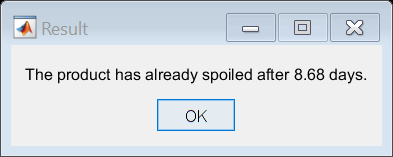


if RSL_days>0
    
    A=sprintf('Remaining shelf-life of the product at the end of %.1f days is %.3f days.',time_rt(end)/(60*24),RSL_days);

else
    A=sprintf('The product has already spoiled after %.2f days.',timeSpoiled_days);
end

msgbox(A,'Result')

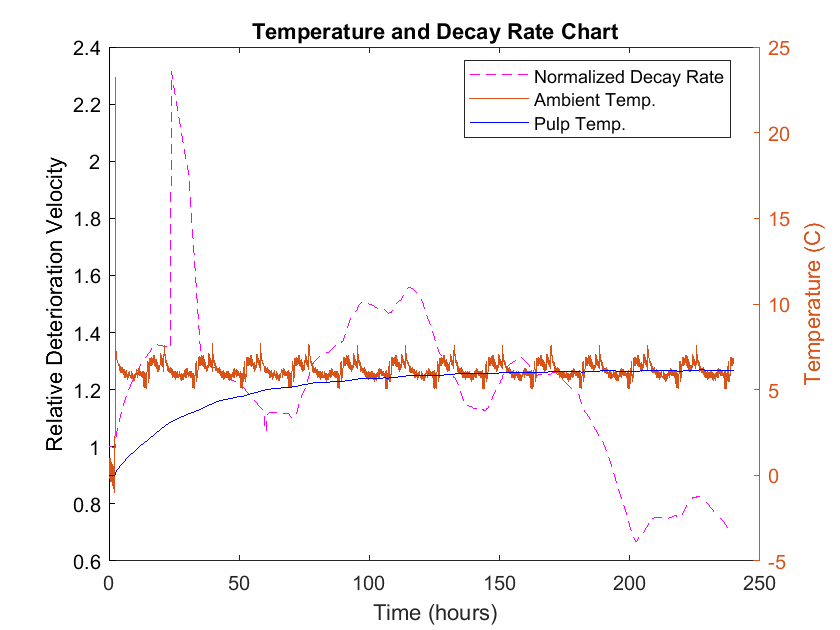

% Plot Normalized decay rate, ambient temperature, and pulp temperature against time
figure
plot(time_rt./60,RealTime_Normal_Resp,'Color','m','LineStyle',"--")
xlabel('Time (hours)')
ylabel('Relative Deterioration Velocity')
title('Temperature and Decay Rate Chart')
yyaxis right
plot(time_rt./60,ambtemp_rt)
hold on
plot(time_rt./60,pulpTemp,'LineStyle','-',"Color",'blue')
hold off
ylabel('Temperature (C)')
legend('Normalized Decay Rate','Ambient Temp.','Pulp Temp.',"Location","best")

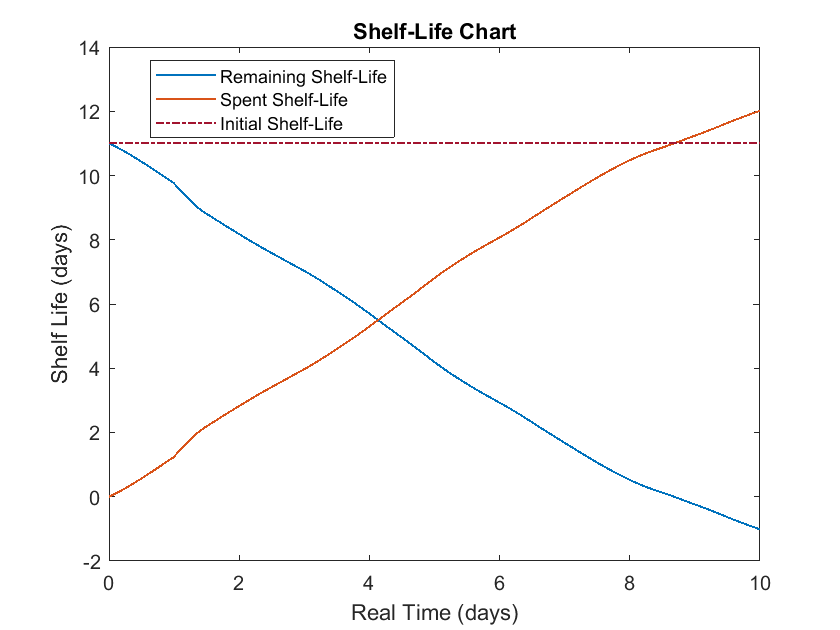


% Plot remaining shelf life and ambient temperature against time

figure

plot(time_rt./(60*24),RSL_days_cum,'LineWidth',1)
xlabel('Real Time (days)')
ylabel('Shelf Life (days)')
title('Shelf-Life Chart')
hold on
plot(time_rt./(60*24),SL_spent_days_cum,'LineWidth',1)
plot([0 time_rt(end)./(60*24)],[SL0 SL0]./24,'Color',[0.6350 0.0780 0.1840],'LineWidth',1,"LineStyle",'-.')
hold off

legend('Remaining Shelf-Life','Spent Shelf-Life','Initial Shelf-Life',"Location","best")


save('Numerical-v14.mat')

### Numerical PDE Solver Functions

function [pl,ql,pr,qr] = heatbc(xl,ul,xr,ur,t)   
global h k_cmpst Tamb  
pl = 0; 
ql = 1;
pr = h*(ur-Tamb);
qr = k_cmpst; 
end

function u0 = heatic(x)
global Ti  
u0=Ti;
end

function [c,f,s] = pdefun(x,t,u,dudx)
global alpha_cmpst k_cmpst egen
c = 1/alpha_cmpst;
f = dudx;
s = egen/k_cmpst;
end
%---------------------------------------------------------------------------------------------------

### 'Quick & Dirty' Method functions

#### Transient without heat generation

function [solT]=TH_PDESolve(symtype,Bi,Fo,X,num_terms)
% symtype=0 for slab, 1 for cylinder, 2 for sphere

zx=0:0.05:num_terms*pi;

% defining the eignefunction according to the symmetry type

switch symtype
    
    case 0
        eigenfun = @(z)z.*tan(z)-Bi; 
    
    case 1
        eigenfun=@(z)z.*besselj(1,z)./besselj(0,z)-Bi;
        
    case 2
        eigenfun=@(z)1-z.*cot(z)-Bi;
        
    otherwise
        error('Symmetry type can only be 0, 1 or 2.')
end
                

% Finding where the eigenfunction changes signs i.e. crosses zero

signzx=diff(sign(eigenfun(zx)));
signzx(isnan(signzx))=0;
signzx_pos=find(signzx);

% candidate roots
z0=zx(signzx_pos);



for j=1:length(signzx_pos)
    
    fval=eigenfun(z0(j));
    
    if isnan(fval)
        
        continue
        
    end
    
    [~,~,exitflag,~]=fzero(eigenfun,z0(j));
    
    if exitflag~=1
        
        Z(j)=NaN;
        
        continue
    else
        Z(j)=fzero(eigenfun,z0(j));
    end
end

% vector of eigenvalues
Z=Z(~isnan(Z));

% plotting the eigenfunction and superimposing eigenvalues to verify

% plot(zx,eigenfun(zx),'color','blue')
% hold on
% plot(Z,eigenfun(Z),'*','color','red')
% legend('Eigenfunction', 'Eigenvalues')
% title('Plot of Eigenfunction and Eigenvalues')
% hold off

% Computing the solution

format long
A=zeros([length(Z),1]);
theta=zeros([length(Z),1]);
    if symtype==0
        
    for i=1:length(Z)
    
            A(i)=4*sin(Z(i))/(2*Z(i)+sin(2*Z(i)));
            theta(i)=A(i)*exp(-Z(i)^2*Fo)*cos(Z(i)*X);
    
    end
    
    elseif symtype==1
        
        for i=1:length(Z)
    
            A(i)=(2/Z(i))*(besselj(1,Z(i))/(besselj(0,Z(i))^2+besselj(1,Z(i))^2));
            theta(i)=A(i)*exp(-Z(i)^2*Fo)*besselj(0,Z(i)*X);
    
        end
        
    elseif symtype==2
        
        for i=1:length(Z)
    
            A(i)=4*(sin(Z(i))-Z(i)*cos(Z(i)))/(2*Z(i)-sin(2*Z(i)));
            theta(i)=A(i)*exp(-Z(i)^2*Fo)*sin(Z(i)*X)/(Z(i)*X);
    
        end
        
    end

theta=theta(~isnan(theta));    
solT=sum(theta);

end
%-----------------------------------------------------------------------------------------------

#### Steady-state with heat generation, given the midplane temperature as a specified temperature boundary condition

function [Tx]=SteadyHeatGen_STBC_midp(symtype,egen,k,Lc,X,Tmidp)

x=X.*Lc;

switch symtype
    case 0
        Tx=Tmidp-egen*(x.^2-(Lc/2).^2)/(2*k);
    case 1
        Tx=Tmidp-egen*(x.^2-(Lc/2).^2)/(4*k);
    case 2
        Tx=Tmidp-egen*(x.^2-(Lc/2).^2)/(6*k);
end
end
%----------------------------------------------------------------------------
function [solS]=SteadyHeatGen(symtype,egen,k,Lc,X,Ts)
x=X.*Lc;
switch symtype
    case 0
        solS=Ts+egen*(Lc.^2-x.^2)/(2*k);
    case 1
        solS=Ts+egen*(Lc.^2-x.^2)/(4*k);
    case 2
        solS=Ts+egen*(Lc.^2-x.^2)/(6*k);
end

end